# Neurotechnology, Brains and Machines: Week 3

Sam Michalka

Most of the content of this notebook is adapted from Kramer, M. A., & Eden, U. T. (2016). *Case Studies in Neural Data Analysis: A Guide for the Practicing Neuroscientist*. MIT Press.  Much of the text is taken directly from their book and their future edX course (under development).

**There is some reading assigned at the end of this notebook, so mentally prepare yourself for the end not being the end.**

This week is pretty stats heavy, so that we can develop a solid understanding of a few fundamentals. Here is what this notebook includes:

- An introduction to neuron spiking data and ways to approach these data (or other data with discrete events at a series of times)

- An explanation of one way that the "best fit" model for a given distribution is selected (maximum likelihood estimation)

- A strategy to determine if your distribution model is appropriate to describe your data (Kolmogorov-Smirnov (KS) plots)

- One strategy for hypothesis testing to evaluate the differences between two conditions (bootstrapping)

- An introduction to the Central Limit Theorem (references to reading and a simulation)

# Study background  

Background

Neurons in the retina typically respond to patterns of light displayed over small sections of the visual field. However, when retinal neurons are grown in culture and held under constant light and environmental conditions, they will still spontaneously fire action potentials. In a fully functioning retina, this spontaneous activity is sometimes described as background firing activity, which is modulated as a function of visual stimuli. It is useful to understand the properties of this background activity in order to determine in future experiments how these firing properties are affected by specific stimuli.

Here is one example video of salamander retinal cells ([https://www.youtube.com/watch?v=ud58gryGr24](https://www.youtube.com/watch?v=ud58gryGr24)). This is not the actual data used here, just a video to give you a sense of what is going on.  You can see the big spikes in the data, which as identified (either by a person or an algorithm) as the cells firing and the spike times can be recorded.  The video actually shows recordings from multiple cells, though our data for this exercise is just from one cell.

Case Study Data

A researcher examining the background firing properties of one of these neurons contacts you to discuss his data. He records the spiking activity in one of two states, with the room lights off (low ambient light levels), or with the room lights on (high ambient light levels). He would like to collaborate with you to determine whether there is a difference in background firing between these two conditions, and whether one environment is more conducive to future experimental analyses. He records the spiking activity for 30 seconds in each condition.

Goals

For spike train data, things can become a bit more complicated. One reason for this is that there are multiple, equivalent ways to describe the same spike train data. The data could be stored as a sequence of spike times, as a sequence of waiting times between spikes, or interspike intervals, or as a discrete time series indicating the number of spikes in discrete time bins. Here, we will begin with basic plotting, and then focus on the interspike intervals (ISIs).

Load in the data.

You can find the data here:

[https://drive.google.com/file/d/1Osy6DFLVjWTxe5RQ1Pt7aU8OAVomtTjH/view?usp=sharing](https://drive.google.com/file/d/1Osy6DFLVjWTxe5RQ1Pt7aU8OAVomtTjH/view?usp=sharing)

load retinaspikedata.mat

You should find two variables now accessible in MATLAB:

SpikesLow - Spike times over 30 s in the low ambient light condition.

SpikesHigh - Spike times over 30 s in the high ambient light condition.

Each variable is a single vector that gives a set of increasing spike times for the associated condition. The two vectors are of different sizes because the neuron fired a different number of spikes in each condition.

**Exercise: How many times did the neuron spike in each condition?**

% Answer code goes here
num_spikes_high = length(SpikesHigh)

num_spikes_high = 969

num_spikes_low = length(SpikesLow)

num_spikes_low = 750

Inspection of the sizes of the vectors SpikesLow and SpikesHigh reveals an important fact: the neuron fires more in the high light condition. To make this observation more concrete, let’s compute the firing rate (f ), defined mathematically as,


$$f=\frac{n}{T}$$


where n is the number of spikes over the time interval T.

**Exercise: Calculate the firing rates for each condition in Hz.**

% Answer code goes here
fHigh = num_spikes_high/30

fHigh = 32.3000

fLow = num_spikes_low/30

fLow = 25

The firing rate computed in this way represents the firing rate for the entire 30 s interval. Is this single number a good representation of the spike train data? What if the spiking changes dramatically throughout the recording? These are important questions to keep in mind as we continue our analysis.

The calculations above allow us to compute a simple number representative of one aspect of the data: the firing rate over the entire duration of the recording. Do the two datasets exhibit a statistically significant change in the firing structure between conditions? Or, does the difference in firing rates lie within the range of expected fluctuations between any two trials of random spiking data?

To answer these types of questions, we will need to develop statistical methods that are appropriate for analyzing spike trains (a time series of data with neurons spiking). We'll start by visualizing the data.

Remember that the values in SpikesLow and SpikesHigh represent the time of the neuron firing. The easiest way to plot the spikes is to put the times on the x-axis and an arbirtary constant on the y-axis.  

You can change the values of xlim in the code below to scroll through the data.

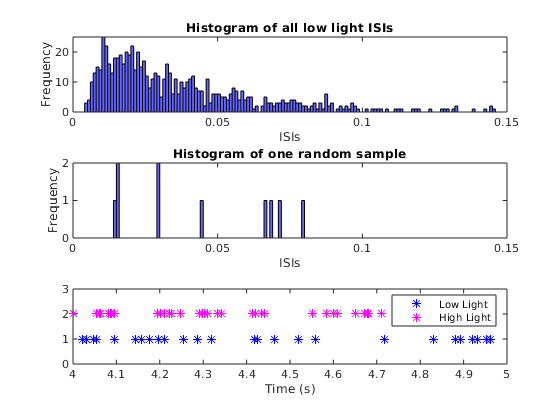

plot(SpikesLow,ones(size(SpikesLow)),'b*');
hold on;
plot(SpikesHigh,2*ones(size(SpikesHigh)),'m*');
hold off; xlabel('Time (s)'); legend({'Low Light', 'High Light'}); ylim([0 3])
xlim([4 5]); %Zoom in to look at 5 seconds of data

With the data visualized in this way, we’re now able to ask an interesting question: What structure do you notice in the two spike trains plotted in above? At first glance, your answer might be: “not much.” Spikes occur fairly regularly throughout the 5 s interval depicted under both conditions. Perhaps a careful visual inspection suggests there are fewer spikes in the low light than in the high light condition. But, the spike times themselves do not seem to be directly comparable between these conditions. 

Often, when we examine data from a stimulus response experiment, we expect to see regions where spiking activity increases or decreases as a function of a changing stimulus. In this case, the stimulus is the ambient light level, which remains constant over the entire experiment. 

**Exercise: Stop and think about other data that might have similar structure: an event that happen at several different times. Name one (or if you can't think of one in a couple of minutes, move on).**

% Answer text goes here

Neutrino detectors (I think.... It's a complicated physics concept and I am not a physicist) 

[https://en.wikipedia.org/wiki/Neutrino_detector](https://en.wikipedia.org/wiki/Neutrino_detector)

# Examine the interspike intervals

So far, we have examined the long term structure of the spiking over multiple seconds. Let’s now focus on the short term structure that occurs within a single second or less. **Change the xlim in the plot above to zoom in on 1 second of data. **

Inspecting smaller time intervals, you might notice “bursts” of spikes that cluster near each other in time, interspersed with longer periods that contain less spiking. These patterns of bursts and quiescence look different between the low and high light stimuli. Visual inspection is an important tool, but we would like a more quantitative result. How might we visualize and compare this fine temporal structure in the two conditions?

One approach to further characterize the differences in spiking between the two conditions is to transform the data. One of the most useful transformations is to focus on the waiting times between the spikes, or interspike intervals (ISIs), instead of the spike times themselves. We can compute the ISIs for the two conditions as follows,

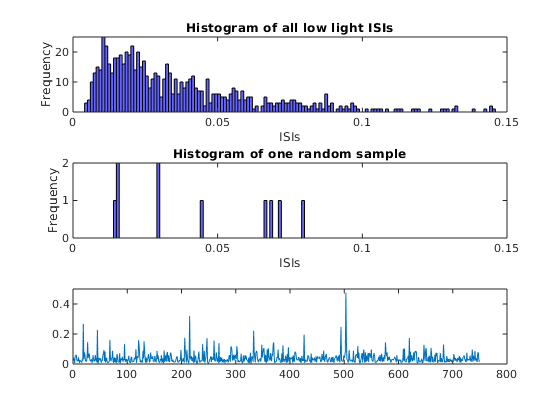

ISIsLow=diff(SpikesLow); %Compute ISIs in low light condition.
ISIsHigh=diff(SpikesHigh);%Compute ISIs in high light condition.

plot(ISIsLow);

Make sure the number of ISIs makes sense to you. Consider how this relates to the spike times and the number of spikes.

**Exercise: Generate histogram(s) to explore the ISIs for the two conditions. Zoom in to examine the ISI values from 0 ms to 150 ms.**

In order to get your two distributions on the same scale, you will need to set the histogram bins. A bin size of 0.001 that maxes out at 0.5 may be helpful.  

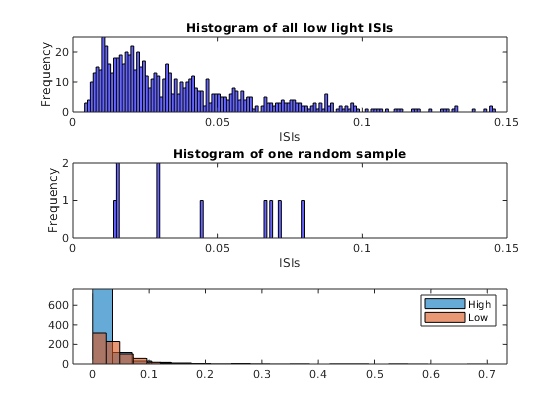

% Answer code goes here
bins = (0:0.001:0.5); %Define the bins for the histogram.
histogram(ISIsHigh, 20);hold on;
histogram(ISIsLow, 20);hold off;
legend("High", "Low")

**Consider the features of the histogram(s). What features of the ISI distributions are similar for the two conditions? What features are most strikingly different? **[reflect, but you don't need to write something]

The high histogram has more very short intervals than the low one.

Now, let's consider how the ISI histogram data relates back to first plot that we generated (time on the x-axis with *s whenever a spike occurred. We conclude from the ISI distribution that many spikes in low light condition are separated by time intervals between 5-20 ms. So, we might be tempted to imagine near-periodic spiking with a period ranging from 5-20 ms (cartoon example "a"). However, the histogram contains additional structure, beyond the single broad peak. Indeed, the histogram has a long tail, with counts extending up to and beyond 150 ms. Therefore, the intervals between spikes are varied; we often see ISIs in the 5-20 ms interval, but we also find much longer ISIs (e.g., from 50 to 150+ ms). The structure of the ISI histogram is consistent with bursting activity; which consists of intervals of rapid spiking, interspersed with quiescence (cartoon example "b").

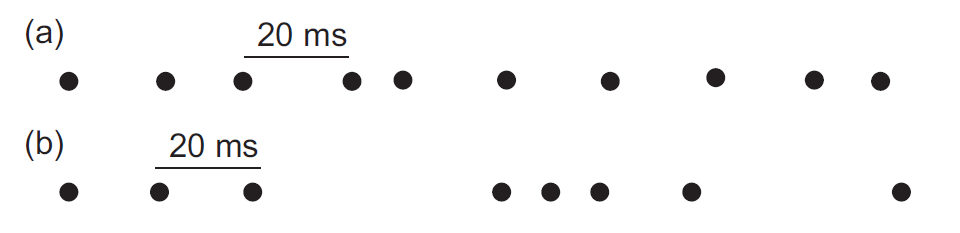

The intervals of rapid spiking produce many shorter ISIs, and the longer intervals produce (typically fewer) longer ISIs. We may conceptualize a bursting neuron as having two timescales: fast and slow. From the shape of the histogram, we conclude that the spike train data in the low light condition are more consistent with bursting activity than periodic, metronome-like, spiking activity.

**Exercise: We claim above that both neurons exhibit bursting activity. But, clearly the two ISI histograms are different. How does the bursting activity differ in the low and high light conditions?**

% Answer text goes here

The histogram showing that the high interval has much more of the smaller gaps between spikes means that the bursts for the high condition contain spikes that are closer to each other. The bursts may also be more frequent, but it is difficult to tell.

# Building a model

We’ll now consider another powerful technique to understand these data: building a model. More specifically, we’ll construct a statistical model of these data. This model will capture important features of the data, but not consist of explicit biophysical components (an example of a biologically explicit model is the Hodgkin-Huxley equations, which you are welcome to look up... we won't cover them in this class). 

The notion of a “model” can be confusing, and is audience dependent, so we’ll be clear here. To construct a statistical model for these data we’ll start by assuming that the ISIs are independent samples from some unknown distribution. We typically posit some class of distributions from which the data might arise, and identify the parameters of that distribution class that maximizes the chance of observing the actual data.

We will start by assuming that our neuron's spiking behavior can be accurately represented by a Poisson process (points randomly located in time). With this assumption, we therefore also assume that our ISIs can be represented with an exponential distribution (these two are mathematically linked: [https://neurophysics.ucsd.edu/courses/physics_171/exponential.pdf](https://neurophysics.ucsd.edu/courses/physics_171/exponential.pdf)).  

Poisson distributions are discrete distributions, which you can investigate in more detail in the optional assignment. For now, we will focus on the interspike intervals (ISIs), which are a continuous distribution. 

We will start by assuming that we can model the ISIs with an exponential function, and we will test this assumption later. The probability density function for an exponential distribution is:


$$y=f\left(x|\mu \right)=\frac{1}{\mu }e^{-\frac{x}{\mu }}$$


where $\mu$ is the mean ISI. This equation is also often expressed this way:


$$y=f\left(x|\lambda \right)=\lambda e^{-\lambda x}$$


where λ is a rate parameter (spikes per second) and is equal to 1/$\mu$. 

These two equations are mathematically equivalent. Matlab uses the equation with $\mu$, but the equation with $\lambda$ is easier to maniplate and relates to the Poisson distribution. We will use both equations below.

Our goal is to find a good value of λ so that our statistical model matches the observed ISI distributions. To start, let’s guess some values for λ, evaluate the model, and see how well the model matches the data. We’ll begin by plotting the probability of observing ISI values in 1 ms bins for the low light condition. This is similar to our ISI histogram we plotted above, except that we will replace the y-axis with “probability” instead of counts. To do so, we simply divide each count value by the total number of ISIs in the low light condition (or have Matlab do this for us by including 'normalization','probability' in the histogram function.

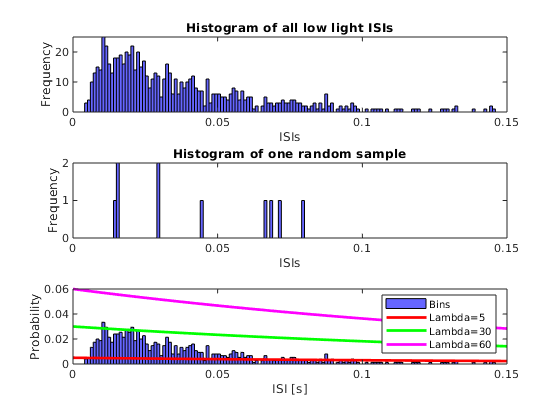

binsize = 0.001; %Create a bin size of 1 ms
bins = (0:binsize:0.5); %Define the bins for the histogram.
histogram(ISIsLow,bins,'normalization','probability','FaceColor','b');
xlim([0 0.15]) %... focus on ISIs from 0 to 150 ms,
xlabel('ISI [s]') %... label the x-axis,
ylabel('Probability') %... and the y-axis.
hold on; %...freeze the graphics window,
lambda = 5; %Choose a value for lambda,
model5 = lambda*exp(-lambda*bins)*binsize; %...and create model, normalizing for bin size
model30 = 30*exp(-lambda*bins)*binsize;
model60 = 60*exp(-lambda*bins)*binsize;
plot(bins,model5, 'r', 'LineWidth',2); %...plot the model in red,
hold on;
plot(bins, model30, "g", 'LineWidth',2);
plot(bins, model60, "m", 'LineWidth',2);
hold off %...and release the window.
legend("Bins", "Lambda=5", "Lambda=30", "Lambda=60")

**Exercise: Add two additional lines to the plot above. One for λ = 30 (green), and one for  λ = 60 (magenta).  By visual inspection, what value of λ provides a good fit to the empirical distribution of the low light condition ISI values?**

% Answer code goes above and text goes here

The lambda value of 30 provides the best fit

The text below talks a little bit about the math behind the maximum likelihood estimate. If you're into this, feel free to dig in. If this is not your style, just give it a quick read and move on.  Here are a few additional resources (or, you know, google): [http://mathworld.wolfram.com/MaximumLikelihood.html](http://mathworld.wolfram.com/MaximumLikelihood.html) ,  [http://www.weibull.com/hotwire/issue33/relbasics33.htm](http://www.weibull.com/hotwire/issue33/relbasics33.htm)

The process above of guessing values of λ and comparing the model to the empirical ISI distribution is not particularly satisfying. How do we identify the parameter λ that best fits the observed ISI distribution? 

Our goal is to find the value of λ that maximizes the likelihood of the data given the statistical model; this value of λ will be our "best fit" of the model to the data. To implement this procedure, let’s consider the probability density of observing a sequence of ISIs, x1, x2, . . . xn. If we assume that the ISIs are independent, then the probability density is,


$$f\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp x_n \right)=f\left(x_1 \right)f\left(x_2 \right)\ldotp \ldotp \ldotp f\left(x_n \right)$$


We call this expression the joint probability distribution of the observed data. In the equation above, we separate the joint probability distribution $f\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp x_n \right)$into a product of probability distributions of each event (i.e., $f\left(x_1 \right)$) - the probability of the first ISI equaling $x_1$, multiplied by $f\left(x_2 \right)$ - the probability of the second ISI equaling $x_2$, multiplied by  $f\left(x_3 \right)$- the probability of the third ISI equaling $x_3$ , and so on). This partitioning of the joint probability is valid here because we assume the ISIs are independent. 

Now, we can replace each probability distribution with the exponential distribution we expect for the ISIs. 


$$f\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp x_n \right)=\lambda \exp \left(-\lambda x_1 \right)\lambda \exp \left(-\lambda x_2 \right)\ldotp \ldotp \ldotp \lambda \exp \left(-\lambda x_n \right)$$


Then we can rewrite the expression as a single exponential that is a function of the unknown rate parameter λ.


$$f\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp x_n \right)=\lambda^n \exp \left(-\lambda \sum_{i=1}^n x_i \right)$$


When considered as a function of the unknown parameters, the joint distribution of the data is also called the likelihood. In this case, we indicate that this is a likelihood funtion by writing the equation as:


$$L\left(\lambda \right)=\;$$

$$\lambda^n e^{-\lambda \left(x_1 +x_2 +\ldotp \ldotp \ldotp +x_n \right)}$$


We experimented with a few values of λ above (5, 30 60).  Remember that λ represents 1/ISI.  Now let's look at this a bit more systematically, by testing a range of λs for the low light condition. 

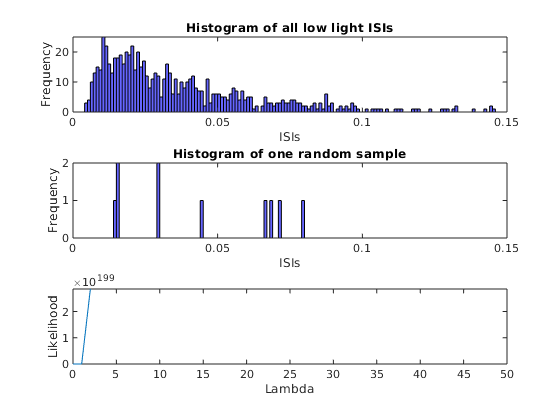

lambdas = 0:1:50; % Range of lambda values
Nlow = length(ISIsLow); % Number of low light
L = (lambdas.^Nlow).*exp(-lambdas*sum(ISIsLow)); %Calculate likelihood
plot(lambdas,L); xlabel('Lambda'); ylabel('Likelihood'); xlim([0 50]);

I suspect this is not the most beautiful plot that you have ever seen. Something appears to have gone wrong. Our y values approach 3 x 10^199 and then vanish. We have exceeded the numerical precision limits of standard Matlab computations by raising λ to the power of Nlow, which is 749.

We can fix this issue by plotting the log of the likelihood, instead of plotting the likelihood directly.  

**Exercise: Calculate and plot the log likelihood (LL) for our range of lambdas.**

Log here refers to the natural log (ln). Here are a few rules for logarithms that might be helpful:


$$\begin{array}{l}
\mathrm{log}\left(x^a \right)=a\;\mathrm{log}\left(x\right)\\
\mathrm{log}\left(e^b \right)=b\\
\mathrm{log}\left(\mathrm{xy}\right)=\mathrm{log}\left(x\right)+\mathrm{log}\left(y\right)
\end{array}$$


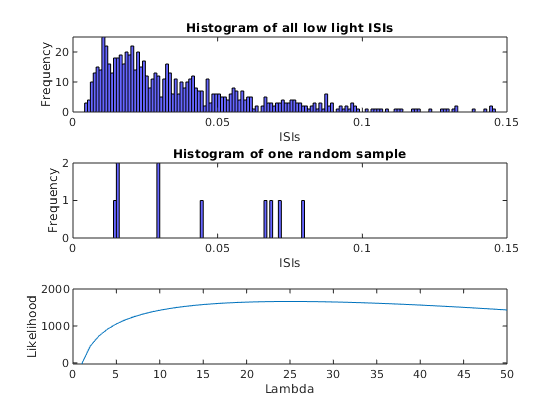

% Answer code goes here
lambdas = 0:1:50; % Range of lambda values
Nlow = length(ISIsLow); % Number of low light
LL = (log(lambdas).*Nlow)-lambdas*sum(ISIsLow); %Calculate likelihood
plot(lambdas,LL); xlabel('Lambda'); ylabel('Likelihood'); xlim([0 50]);

Here, the value that maximizes that log likelihood gives us our estimated λ for the "best fit" of the exponential distribution. This is often referred to as the maximum likelihood estimation (MLE).  Again, we are using this to find the value of λ that maximizes the likelihood of the data given the statistical model.  We can find this using the following code:

maxLL = max(LL)

maxLL = 1.6622e+03

estlambda = lambdas(LL==maxLL) %find the value of lambda where LL is maxLL

estlambda = 25

As we looked at previously, the probability density function for an exponential distribution is:


$$y=f\left(x|\mu \right)=\frac{1}{\mu }e^{-\frac{x}{\mu }}$$


where $\mu$ is the mean ISI. So far, we have been using this form of the expression (because it's easier to deal with for the log likelihood calculation): 


$$y=f\left(x|\lambda \right)=\lambda e^{-\lambda x}$$


where λ is a rate parameter (spikes per second) and is equal to 1/$\mu$. 

Now we can evaluate the relationship between λ and $\mu$.

format long
meanISIsLow = mean(ISIsLow) % We don't know the population mean, but we estimate it with the sample mean

meanISIsLow =    0.039988397284383



1/meanISIsLow

ans =   25.007253801355365


These numbers are very close. Remember that we only evaluated the lambdas in increments of 1. 

In this example, we could actually just estimate our parameter (either  λ or $\mu$) using the theortical solution ($\lambda =\frac{1}{\textrm{mean}\left(\textrm{ISIs}\right)}$ ). For some statistical models, it is convenient to compute maximum likelihood estimates theoretically in this manner, but sometimes no closed form solution exists. Often, we will use numerical methods to solve for the maximum likelihood estimates. 

We walked through the process of finding the maximum likelihood estimate to help build an intuition about how MLE works. However, we can easily just have Matlab do this for us (what a luxurious life we live).  Matlab uses the form of the equation with $\mu$ instead of λ.

modelexplow = fitdist(ISIsLow','Exp') %Need to transpose to make column vector to make fitdist happy

modelexplow =   ExponentialDistribution

  Exponential distribution
    mu = 0.0399884   [0.0372723, 0.0430141]


This gives us the estimated value for the parameter $\mu$ and [confidence intervals around this estimate]. More on confidence intervals in the future.

In our first pass through, we calculated the maximum log likelihood (maxLL).  The fitdist function also calcuates the log likelihood, but stores this as the negative log likihood. The negative log likelihood is often used because we love to minimize things. Note that these two values are almost identical, except for the sign.

format short
maxLL

maxLL = 1.6622e+03

modelexplow.negloglik

ans = -1.6622e+03

Plot both versions of the model to show that they are the same and to observe how they fit the data.

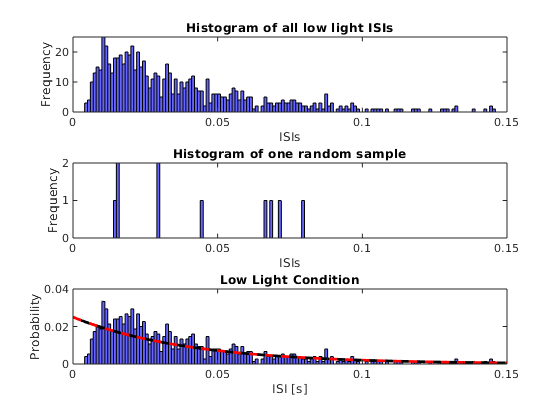

binsize = 0.001; %Create a bin size of 1 ms
bins = (0:binsize:0.5); %Define the bins for the histogram.
histogram(ISIsLow,bins,'normalization','probability','FaceColor','b');
xlim([0 0.15]) %... focus on ISIs from 0 to 150 ms,
xlabel('ISI [s]'); ylabel('Probability'); title('Low Light Condition');
hold on; %...freeze the graphics window,
lambda = estlambda; %Choose a value for lambda,
modellow = lambda*exp(-lambda*bins)*binsize; %...and create model, normalizing for bin size
plot(bins,modellow, 'k', 'LineWidth',2); %...plot the model in black
plot(bins,modelexplow.pdf(bins).*binsize, 'r--', 'LineWidth',2)
hold off %...and release the window.

**Exercise: Find and plot the best fit exponential model for the high light condition.**

You only need to calculate this one way. It's probably most interesting to plot this along with the histogram.

% Answer code goes here
clear lambdas LL 
lambdas = 0:1:50; % Range of lambda values
Nhigh = length(ISIsHigh); % Number of low light
LL = (log(lambdas).*Nhigh)-lambdas*sum(ISIsHigh); %Calculate likelihood

maxLL = max(LL)

maxLL = 2.3964e+03

estlambda = lambdas(LL==maxLL)

estlambda = 32

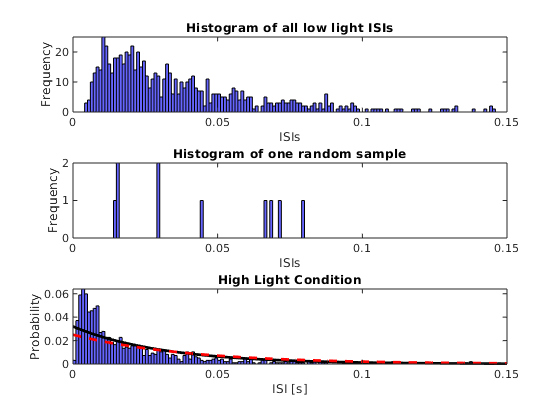


binsize = 0.001; %Create a bin size of 1 ms
bins = (0:binsize:0.5); %Define the bins for the histogram.
histogram(ISIsHigh,bins,'normalization','probability','FaceColor','b');
xlim([0 0.15]) %... focus on ISIs from 0 to 150 ms,
xlabel('ISI [s]'); ylabel('Probability'); title('High Light Condition');
hold on; %...freeze the graphics window,
lambda = estlambda; %Choose a value for lambda,
modelhigh = lambda*exp(-lambda*bins)*binsize; %...and create model, normalizing for bin size
plot(bins,modelhigh, 'k', 'LineWidth',2); %...plot the model in black
plot(bins,modelexplow.pdf(bins).*binsize, 'r--', 'LineWidth',2)
hold off %...and release the window.

# Assessing our model assumption

We have determined the best fit for the exp distribution using the log likelihood. But is this really an appropriate distribution to descibe our data?

To go beyond visual inspection of the model fits and quantify the goodness-of-fit, we will compare the cumulative distributions computed from the data and model. Remember that the cumulative distribution function (CDF) is the probability that a random variable will take on a value less than or equal to x.

We can calculate the empirical (from data) cdf using the ecdf function. The model cdf is one of the methods available in the distribution object (myobject.cdf) which evaluates the cdf at a vector of values (ebins). 

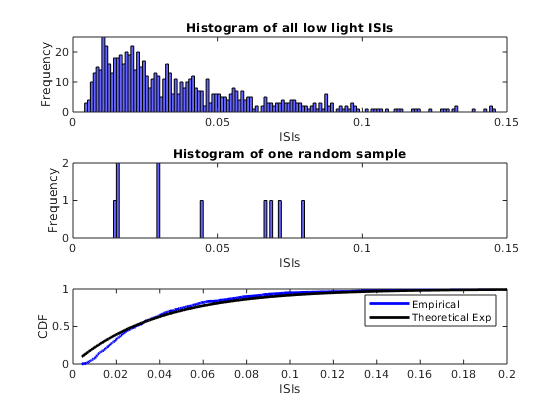

[empcdflow,ebins] = ecdf(ISIsLow); 
plot(ebins, empcdflow,'b','LineWidth',2);
hold on
plot(ebins, modelexplow.cdf(ebins),'k','LineWidth',2)
xlabel('ISIs'); ylabel('CDF'); legend({'Empirical','Theoretical Exp'})
xlim([0 .2]); %zoom in for better view
hold off;

If you hate that the model distribution doesn't extend to 0, you can create a different input vector (eg., tbins = 0:0.001:max(ebins);). However, you should not do this for the KS plots below.

Another common way to visualize the difference between the model and empirical distributions is a Kolmogorov-Smirnov (KS) plot. This is just a plot of the empirical CDF against the model CDF directly (instead of both of these separately vs the ISIs).  Here, we need to use the ebins to generate the theoretical cdf values.

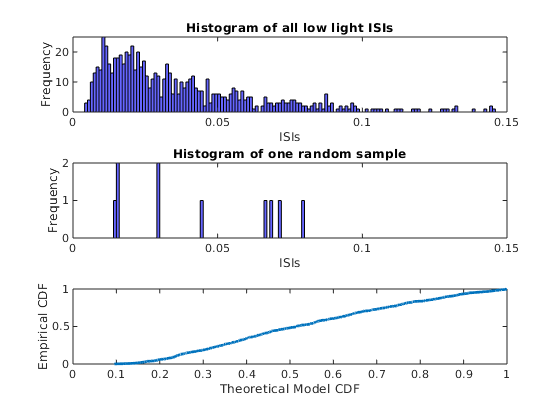

plot(modelexplow.cdf(ebins),empcdflow,'LineWidth',2);
xlabel('Theoretical Model CDF'); ylabel('Empirical CDF');

Since the KS plot compares CDFs, both the x and y axes range from 0 to 1. A perfect fit between the model and empirical CDFs would look like a straight, 45 degree line between the points (0,0) and (1,1). Any deviation from this line represents deviation between the observed and model distributions.

One nice result for comparing CDFs is that with enough data, the maximum difference between the model and empirical CDF has a known asymptotic distribution, which can be used to put confidence bounds about the KS plot. For 95% confidence bounds, a well-fit model should stay within $\frac{\pm 1\ldotp 36}{\sqrt{N}}$ of the 45 degree line, where N is the number of ISIs observed.

**Exercise: Place these confidence bounds on our KS plot. You may need to reset your axes to be between 0 and 1**

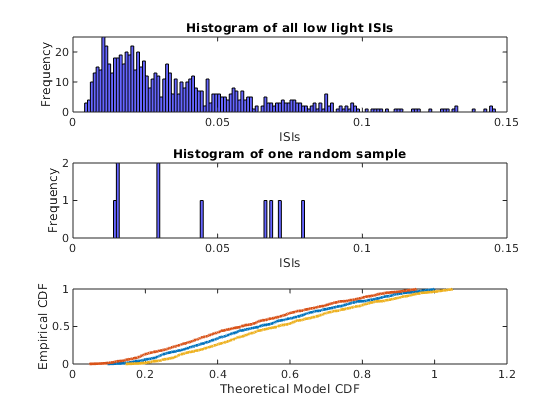

% Answer code goes here
% I'm not sure if this is right
plot(modelexplow.cdf(ebins),empcdflow,'LineWidth',2);
hold on;
plot(modelexplow.cdf(ebins)-0.05,empcdflow,'LineWidth',2);
plot(modelexplow.cdf(ebins)+0.05,empcdflow,'LineWidth',2)
xlabel('Theoretical Model CDF'); ylabel('Empirical CDF');
hold off;

A well-fit model should stay entirely within these bounds. In this case, the KS plot for the low light condition extends well outside these bounds. The exponential ISI model does not fit the data in the low light condition well. This suggests that we need a better model if we want to make meaningful comparisons about differences in the structure of the data between the two conditions.

**Exercise: Generate a KS plot with 95% confidence bounds for the high light condition. **

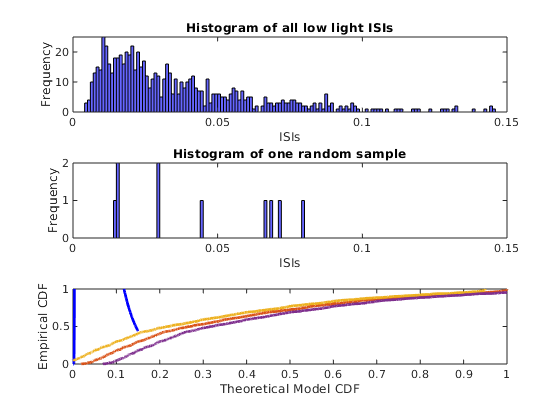

% Answer code goes here
[empcdfhigh,ebins] = ecdf(ISIsHigh); 
plot(modelexplow.cdf(ebins),empcdfhigh,'LineWidth',2);
hold on;
plot(modelexplow.cdf(ebins)-0.05,empcdfhigh,'LineWidth',2);
plot(modelexplow.cdf(ebins)+0.05,empcdfhigh,'LineWidth',2)
xlabel('Theoretical Model CDF'); ylabel('Empirical CDF');
hold off;

axis([0 1 0 1]) %... with fixed axes.
hold off

# Fitting a different model

We’ve now investigated one class of models - the exponential distribution - to fit the observed ISI distributions. However, through our analysis, we’ve found that this statistical model is not sufficient to mimic the observed data.  In the KS plots above, our line often fell well outside the bounds of our 95% confidence bounds.

There are many other choices for statistical models; let’s try one other class of models now. The inverse Gaussian probability model has been used successfully to describe ISI structure in this system by previous researchers. The probability density function is: 


$$f\left(x\right)=\;\sqrt{\frac{\lambda }{2\pi x^3 }}\exp \left(\frac{-{\lambda \left(x-\mu \right)}^2 }{2x\mu^2 }\right)$$


The inverse Gaussian distribution has two parameters that determine its shape: μ, which determines the mean of the distribution, and λ, which is called theshape parameter. Also known as the Wald distribution, the inverse Gaussian is used to model nonnegative positively skewed data. Specifically, at x = 0, the inverse Gaussian has a probability density equal to zero, which suggests it could capture some of the refractoriness seen in the data.  Refractoriness refers to the very small number of ISIs that are smaller than 1 ms, which is due to the refractory period of the neuron (it's very hard for the neuron to fire within 1 ms of the last time it fired).

We can use MATLAB to find the maximum likelihood solution for the parameter estimates ($\mu^‾ ,\lambda^‾$) that maximes the likelihood of the data, again using fitdist().

modelinvgausslow = fitdist(ISIsLow','InverseGaussian') % Create theoretical distribution: inverse gaussian

modelinvgausslow =   InverseGaussianDistribution

  Inverse Gaussian distribution
        mu = 0.0399884   [0.0374097, 0.0425671]
    lambda = 0.0493182   [0.0443232, 0.0543131]


The names of the model parameters can be found within the distribution object.

modelinvgausslow.ParameterNames %useful if we don't know the parameter names

ans = 1×2 cell array
    {'mu'}    {'lambda'}


modelinvgausslow.mu

ans = 0.0400

modelinvgausslow.lambda

ans = 0.0493

We will also want to generate a histogram with our distribution overlaid. We can either scale the pdf values by the bin size (as we did previously), or use the 'pdf' normalization option instead of the 'probability' normalization option.  With the pdf normalization, the values on the y-axis are not probabilities.

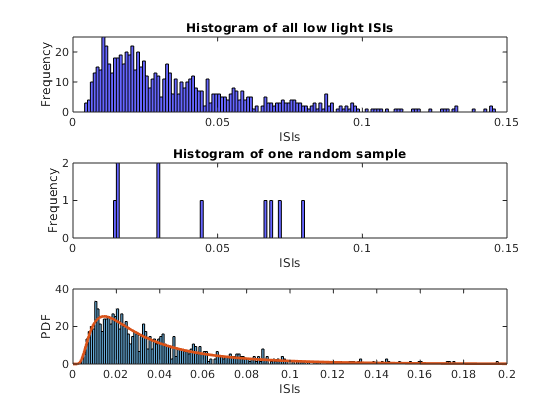

binsize = 0.001;
bins = (0:binsize:0.5); %Define the bins for the histogram.
histogram(ISIsLow,bins,'normalization','pdf') % 
hold on
plot(bins,modelinvgausslow.pdf(bins),'LineWidth',2);
xlabel('ISIs'); ylabel('PDF'); 
xlim([0 .2]); %zoom in for better view
hold off;

**Exercise: Create a KS plot for the inverse gaussian model of the low light condition.**

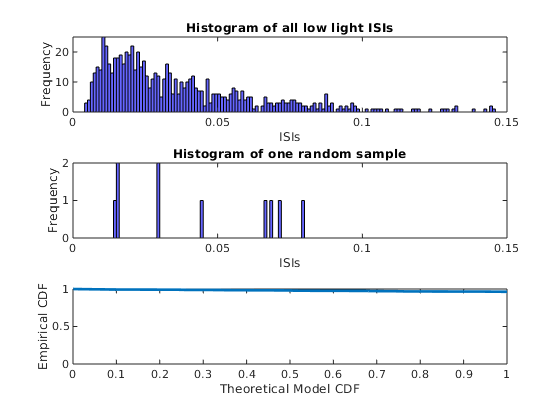

% Answer code goes here
bins = (0:0.0001:0.15);
[empcdfhigh,bins] = ecdf(ISIsLow); 
plot(modelinvgausslow.pdf(bins),empcdflow,'LineWidth',2);
hold on;
xlabel('Theoretical Model CDF'); ylabel('Empirical CDF');
hold off;

axis([0 1 0 1]) %... with fixed axes.
hold off

We can also compare the two model fits. Remember that we are looking at the negative log likelihood, so smaller is better.

modelinvgausslow.negloglik

ans = -1.7764e+03

modelexplow.negloglik

ans = -1.6622e+03

**Exercise: Do you think that the inverse gaussian model is an appropriate choice for these data? Why?**

% Answer text goes here.

The log likelihoods are very small (similarly small) and the model seems to fit well from visual inspection.

**Exercise: Fit and evaluate the inverse gaussian model for the high light condition.  Do you think that the inverse gaussian model is an appropriate choice for these data? Why?**

% Answer code goes here

modelinvgausshigh = fitdist(ISIsHigh','InverseGaussian') 

modelinvgausshigh =   InverseGaussianDistribution

  Inverse Gaussian distribution
        mu =   0.030942   [0.0274238, 0.0344601]
    lambda = 0.00949814   [0.00865195, 0.0103443]



modelinvgausshigh.ParameterNames %useful if we don't know the parameter names

ans = 1×2 cell array
    {'mu'}    {'lambda'}


modelinvgausshigh.mu

ans = 0.0309

modelinvgausshigh.lambda

ans = 0.0095

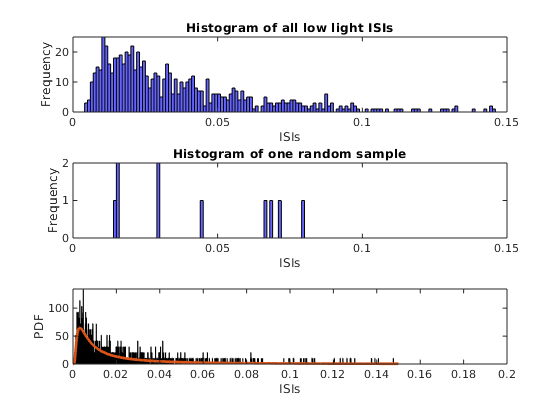


histogram(ISIsHigh,bins,'normalization','pdf') % 
hold on
plot(bins,modelinvgausshigh.pdf(bins),'LineWidth',2);
xlabel('ISIs'); ylabel('PDF'); 
xlim([0 .2]); %zoom in for better view
hold off;

% Answer text goes here.

The model does not seem to be quite as good of a fit for this data, but I might have done something wrong

# Comparing the high and low light conditions

Alas, we are now ready to compare our two conditions. We will begin by asking if the estimates for the paramter $\mu$ in the inverse gaussian model are different for the two conditions.  First, here are our two models visually:

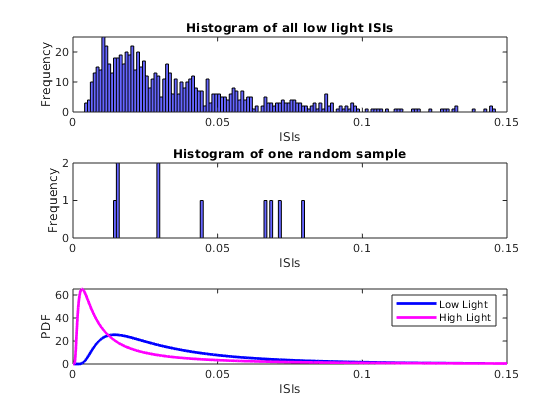

bins = (0:0.0001:0.15); 
plot(bins,modelinvgausslow.pdf(bins),'b','LineWidth',2); hold on
plot(bins,modelinvgausshigh.pdf(bins),'m','LineWidth',2); 
legend({'Low Light','High Light'});
xlabel('ISIs'); ylabel('PDF'); hold off

We can just compare these two parameter estimates for mu:

modelinvgausslow.mu % Parameter estimate (mu) for low light

ans = 0.0400

modelinvgausshigh.mu % Parameter estimate (mu) for low light

ans = 0.0309

lowminushighmu = modelinvgausslow.mu - modelinvgausshigh.mu  % Difference

lowminushighmu = 0.0090

We observe that there is a 9 ms difference in the mean ISIs between the two conditions. We didn't actually need to build our models to determine this... mean(ISIsLow) - mean(ISIsHigh) would also work.

This brings us to one of the major questions of inferential statistics:

**Is this difference meaningful or is it likely the result of random variations in our measurement?**

or... **Is this difference statistically significant?**

There are multiple ways to address this question. Previously, we have explored questions like this with a t-test. Here, we are going to conduct a bootstrap analysis. To do so, we: 

1) combine all of the ISIs from both conditions into one pool,

2) sample many new datasets with replacement from that pool, and 

3) compare the actual difference in our parameters ($\mu$) to the distribution of differences across our samples.

ISIs = [ISIsLow ISIsHigh]; % Combine all the ISIs from both conditions into one pool
Nall = length(ISIs); %Length of all ISIs combined
Nlow = length(ISIsLow); % Length of low light condition
Nhigh = length(ISIsHigh); % Length of high light condition
Nboots = 100; % Number of bootstrap iterations

sampDiff = zeros(Nboots,1);
for i = 1:Nboots  % For each bootstrap iteration
    sampLo = ISIs(randsample(Nall,Nlow,1)); % random sample with replacement of ISIs that is length of Nlo
    sampHi = ISIs(randsample(Nall,Nhigh,1)); % same for Nhi
    sampDiff(i) = mean(sampLo) - mean(sampHi); %store the difference in a vector
end


Now we can plot the distribution of all of the sample differences that we calculated in our bootstrap analysis above.

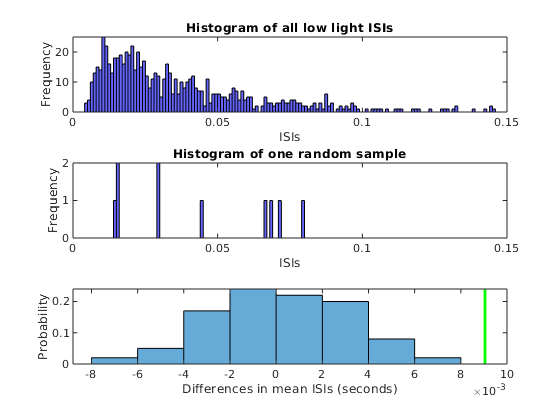

h = histogram(sampDiff, 'normalization', 'probability'); %storing the output of histogram gives us useful info
hold on
plot([lowminushighmu lowminushighmu],[0 max(h.Values)],'g','LineWidth',2)
xlabel('Differences in mean ISIs (seconds)'); ylabel('Probability');
hold off

**Exercise: What are the effects of changing the number of bootstraps?**

% Answer text goes here.

The number of bootstraps is the number of times you take one random sample, so it affects how standard the distribution in the last graph is

We can use this bootstrapped distribution to conduct a hypothesis test. 

This comparison is an example of a two-tailed test, since we have not established an *a priori* justification for one of our paramter estimates of $\mu$ to be higher than the other (either the low or the high light condition could have a higher parameter estimate). 

In classical hypothesis testing, we would find our "critical values" from a theoretical distribution (such as a z-distribution or a t-distribution). 

In the bootstrapping case, we actually created an empirical distribution of our differences in ISI sample means.  Therefore, we can just use this empirical distribution to determine our critical values.  

**Exercise: Determine if our observed difference in the parameter estimates for mu (lowminushighmu) falls outside of the middle 95% of bootstrapped values.**

This is another way of saying, conduct a two-tailed test on the bootstrapped distribution where $\alpha =0\ldotp 05$. If our observed value of lowminushighmu falls outside of these critical values, then we would reject the null hypothesis that parameter estimates of mu for the two conditions are the same.

The prctile() function might be useful. Note that this takes in a value of P that is between 0 and 100 (not 0 to 1).

% Answer code goes here
prctile(sampLo, 5)

ans = 0.0028

prctile(sampLo, 95)

ans = 0.1086

[h,p,ci,stats] = ttest2(sampLo, sampHi)

h = 0

p = 0.6052

ci =    -0.0062    0.0036


stats = struct with fields:
    tstat: -0.5170
       df: 1715
       sd: 0.0518


% Answer text goes here.

**Optional Exercise: Conduct a bootstrap analysis to compare the estimated values of lambda for the two conditions. Are the values of lambda different? What does this suggest about the two distributions?  **

You either need to find the theoretical way to estimate the values of lambda or fit each sample distribution and get the estimated lambda from this fitted distribution.

% Answer text goes here

# Central Limit Theorem

You may have noticed that the distribution of the differences in the mean ISIs above had a different shape than the distributions of ISIs themselves. In fact, this distribution of differences looked rather Normal, while the distribution of ISIs was not Normal (it was quite positively skewed).  There was a lot going on in the analysis above: we were taking the mean ISI of each sample and then subtracting them from each other to create our distribution.  

Let's take a step to simplify things and investigate this phenomenon by just looking at the mean ISI for the low light condition. We will build a distribution of sample means. To do this, we will

1) Take a sample (with replacement) of size n from the vector of ISIs for the low light condition.

2) Calculate the mean of this sample of ISIs.

3) Store the mean calcuated in step 2 in a new distribution (distribution of sample means).

4) Repeat this process a number of times (Nrep).

ans = 0.0400

ans = 0.0400

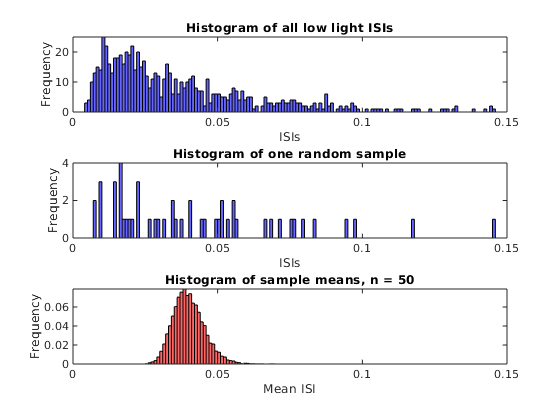

n = 50; % Number of ISIs in our sample, ie, our sample size
Nrep = 10000; % Number of times to repeat the process

distofsamplemeans = zeros(1,Nrep); %Vector to store the sample means
for i = 1:Nrep %for each repetition
    ISIsample = ISIsLow(randsample(length(ISIsLow),n,1)); %Choose a random sample with replacement from the ISIsLow
    distofsamplemeans(i) = mean(ISIsample);
end

% Calculate the mean of the whole ISIsLow data and compare to the mean of the samplemeans
mean(ISIsLow)
mean(distofsamplemeans)

subplot(3,1,1);
bins = (0:0.001:0.5); %Define the bins for the histogram.
histogram(ISIsLow,bins,'FaceColor','b'); xlim([0 0.15]); xlabel('ISIs'); ylabel('Frequency'); title('Histogram of all low light ISIs');
subplot(3,1,2);
histogram(ISIsample,bins,'FaceColor','b'); xlim([0 0.15]);  xlabel('ISIs'); ylabel('Frequency'); title('Histogram of one random sample');
subplot(3,1,3);
histogram(distofsamplemeans,bins,'FaceColor','r','normalization','probability'); xlim([0 0.15]);  xlabel('Mean ISI'); ylabel('Frequency'); title(['Histogram of sample means, n = ' num2str(n)]);

**Exercise: Run this simulation for different values of the sample size n.  What happens as n increases?**

% Answer text goes here.

As n increases the final distribution of sample means becomes more close (the standard distribution decreases) 

Consider how this related to the central limit theorem. If the central limit theorem is still fuzzy, these resources might be helpful:

- Khan academy video (https://www.khanacademy.org/math/statistics-probability/sampling-distributions-library/sample-means/v/central-limit-theorem)

- Mathematical proofs (http://www.cs.toronto.edu/~yuvalf/CLT.pdf or http://mathworld.wolfram.com/CentralLimitTheorem.html)

- Java simulation that allows you to draw your starting distribution (http://onlinestatbook.com/stat_sim/sampling_dist/)

*The end.*